## Ligninger

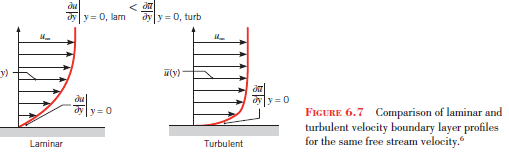

## Opgaver

## Opgave 6.33

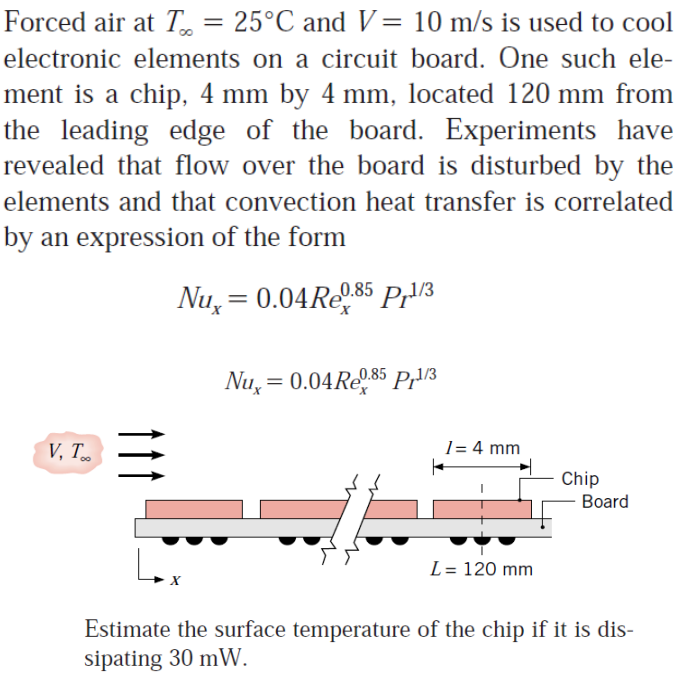

clear all
fluid = 'Air'
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure
T_inf = 25 +273.15; %K

c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_inf, fluid) %specificHeat_p
k = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_inf, fluid) %thermalConductivity
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_inf, fluid) %Dynamisk viscositet
rho = CoolProp.PropsSI('D', 'P', P, 'T', T_inf, fluid); %Densitet
V = 10; %m/s
l = 4e-3; %m
L = 0.120; %m
% mu = 1.84e-5; % kg/(m·s) eller N⋅s/m2
q = 30e-3; % W
% c_p = 1007; %J/kg⋅K
% k = 26.3e-3; %W/m⋅K varme conductivitet
A = l * l
nu = mu/rho %kinematisk viskositet %1.5577e-5; 

Re_x = V*L/nu
Pr = c_p * mu / k

Nu_x = 0.04*Re_x^(0.85) * Pr^(1/3)

h = Nu_x/L * k
% R_tot = 1/(h*A)

syms T_sym
T = solve(q == (T_sym - T_inf) * h*A, T_sym);
vpa(T - 273.5, 5)

q/(A*h) + 25


## Figurer og tabeller